%{
ES115- Class-Project Module 1 project bank
Author: Matthew Chietro
Version: 1.0
Date: 2026-04-6
Purpose:
    - To plot graphs of an autonumous car speed profile for speed vs time
    and acceleration vs time while also finding the estimated acceleration.
    We will use this to identify the when the speed reaches the maximum and
    what the estimated acceleration at that point is.
Input:
    - number indicating which button was pressed
Output:
    - Name stacked above date in panel title
    - Display age in years to two places of decemal
    - Display age in days to one place of decemal
Engineering Algarithems:
    - Clear the screen and delete all variables
    - Package the panel title information as a matrix of strings
    - Rap menu and switch/case is a forever while loop 
    - When button one is pressed display age in years
    - When button two is pressed display age in days
    - When button three is pressed exit while loop and end program
MATLAB tools/functions:
    - While loop, menu, datetime, fprintf, switch/case, 
    - User function with return value but no argument. 
%}

Autonomous Cart Speed Profile (Quadratic + Numerical Change)

A small autonomous cart follows a speed profile over time modeled by:

v(t) = −0.2(t − 10)2 + 20

for 0 ≤ t ≤ 20 seconds.

Tasks

1. Implement v(t) and evaluate it on t = 0 : 0.2 : 20.

t = 0:0.2:20;           % time vector (seconds)
v = -0.2*(t - 10).^2 + 20;  % speed profile (m/s)

2. Plot speed vs time.

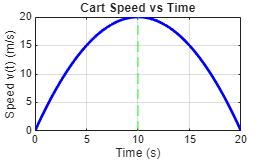

figure(1);
plot(t, v, 'b-', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Speed v(t) (m/s)');
title('Cart Speed vs Time');
xline(10,'g--','LineWidth',1);
grid on;

3. Use numerical differences to estimate the acceleration a(t) ≈ ∆v

∆t .

dt = t(2) - t(1);       % this defines the change in time
a = diff(v) / dt;       % numerical derivative (acceleration)
t_a = t(1:end-1) + dt/2; % associate acceleration at midpoints

4. Plot acceleration vs time on a separate figure.

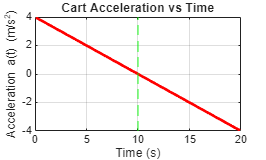

figure(2);
plot(t_a, a, 'r-', 'LineWidth', 2);
xlabel('Time (s)');
ylabel('Acceleration a(t) (m/s^2)');
title('Cart Acceleration vs Time');
xline(10,'g--','LineWidth',1);
grid on;

5. Identify the time when speed is maximized and interpret what acceleration is near that time

[v_max, idx_max] = max(v);
t_max = t(idx_max);  % time of maximum speed
a_at_max = a(idx_max-1);  % approximate acceleration near max speed
fprintf('Maximum speed = %.2f m/s occurs at t = %.2f s\n', v_max, t_max);

Maximum speed = 20.00 m/s occurs at t = 10.00 s


fprintf('Acceleration near max speed ≈ %.2f m/s^2\n', a_at_max);

Acceleration near max speed ≈ 0.04 m/s^2
